# MXB201 Solutions 4

## Theory

T1.  Prove that  if $v_1$ and $v_2$ are eigenvectors of a symmetric matrix associated with eigenvalues $\lambda_1$ and $\lambda_2$ respectively, with$\lambda_1 \neq \lambda_2$, then $v_1 \cdot v_2 = 0$.

Consider $\lambda_1{v_1}^T v_2 =  (\lambda_1 v_1)^T v_2 = (Av_1)^T v_2 = {v_1}^T A^T v_2 = {v_1}^T Av_2 = {v_1}^T \lambda_2 v_2 = \lambda_2  {v_1}^T v_2 $

Equating the first and last expressions in this chain, $\lambda_1{v_1}^T v_2 = \lambda_2{v_1}^T v_2$, implying that $(\lambda_1-\lambda_2){v_1}^T v_2 = 0$.

Now, since $\lambda_1 \neq \lambda_2$ by hypothesis, we must have ${v_1}^T v_2 = 0$, i.e. $v_1 \cdot v_2 = 0$.

T2.  Let $A \in \mathbb{R}^{n \times n}$.  If $(\lambda, v)$ is an eigenpair of $A$, prove that $(\lambda^k, v)$ is an eigenpair of $A^k$  ($k$ is a positive integer).

We prove by induction.  $Av = \lambda v$ is the base case.  Assume $A^{k-1} v = \lambda^{k-1} v$.  Now multiply both sides by $A$.

The left hand side is $A A^{k-1} v = A^k v$.

The right hand side is $A \lambda^{k-1} v = \lambda^{k-1} A v = \lambda_{k-1} \lambda v = \lambda^k v$.

So $A^k v = \lambda^k v$ as required.

T3.  Let $A \in \mathbb{R}^{m \times n}$.  Prove that $A^T A$ and $AA^T$ have the same nonzero eigenvalues.Try a couple of random matrix examples in MATLAB to convince yourself first.

Let $(\lambda, v)$ be an eigenpair of $A^T A$.  So $(A^T A) v = \lambda v$.

Multiply both sides by $A$:  $A(A^TA)v = A \lambda v$.

Changing the parenthesisation makes it clear: $(AA^T)(Av) = \lambda (Av)$

If $Av = 0$ then $v$ is in the null space of $A$, and hence of $A^TA$ too.  So $v$ is an eigenvector of $A^TA$ with eigenvalue $\lambda = 0$.

If $Av \neq 0$, then $Av$ is an eigenvector of $AA^T$ with the same eigenvalue $\lambda$.

Hence, if $\lambda$ is a nonzero eigenvalue of $A^TA$, then it is also an eigenvalue of $AA^T$.

Analagous reasoning would hold in the reverse: let $(\mu, w)$ be an eigenpair of $AA^T$ and multiply both sides by $A^T$.

T4.  Show that the eigenvalues of $A^TA$ are all non-negative.  That is, $A^TA$ is symmetric positive semi-definite.

Consider the eigenpair $(\lambda, v)$, so that $A^TA v = \lambda v$.  Multiply by $v^T$ both sides: $v^T A^T A v = v^T \lambda v = \lambda \|v\|^2$.

But also, for any vector $v$, $v^T A^T A v = (Av)^T(Av) = \|Av\|^2$.

Equating: $\lambda \|v\|^2  = \|Av\|^2$.

Hence $\lambda = \|Av\|^2 / \|v\|^2$, which is non-negative.

T5.  Show that if $A$ has full column rank then $A^TA$ is symmetric positive definite.

A symmetric matrix is positive definite if and only if all its eigenvalues are positive.

From T4, we showed all eigenvalues of $A^TA$ are of the form $\lambda = \|Av\|^2 / \|v\|^2 \geq 0$.

If we now also impose that $A$ has full column rank, then $Av$ cannot be zero, and hence $\lambda > 0$.

Alternatively, using the definition of positive definite: a matrix $M$ is postive definite if $x^T M x > 0$ for all $x \neq 0$.

If $M = A^TA$ then we require $x^T A^T A x > 0$.

But $x^T A^T A x  = (Ax)^T (Ax) = \|Ax\|^2 \geq 0$.  So $A^TA$ is certainly positive *semi*definite.

Positive definite requires strict inequality, but since we know $A$ has full column rank, $Ax$ cannot be zero, and hence neither can $\|Ax\|$.

So $A^TA$ is indeed symmetric positive definite.

## Practice

P1.  For each of these matrices, run `animate_matrix(A)` and deduce as much as you can about the eigenvalues and eigenvectors of $A$.  Then, calculate them (if you want the practice) or get MATLAB to do it, to confirm.

A1 = sym([2, 0 ; 0, 1])

$$A1 = \left(\begin{array}{cc} 2 & 0\\ 0 & 1 \end{array}\right)$$

A2 = sym([2, 0 ; 0,-1])

$$A2 = \left(\begin{array}{cc} 2 & 0\\ 0 & -1 \end{array}\right)$$

A3 = sym([0, 1 ; 1, 0])

$$A3 = \left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$

A4 = sym([0, 1 ;-1, 0])

$$A4 = \left(\begin{array}{cc} 0 & 1\\ -1 & 0 \end{array}\right)$$

A5 = sym([1, 1 ; 1, 1])

$$A5 = \left(\begin{array}{cc} 1 & 1\\ 1 & 1 \end{array}\right)$$

A6 = sym([1, 1 ; 0, 1])

$$A6 = \left(\begin{array}{cc} 1 & 1\\ 0 & 1 \end{array}\right)$$

P2.  Find the orthogonal diagonalisation of

A = sym([
     7    -1     1     0    -2
    -1     8     2     0     1
     1     2     8     0    -1
     0     0     0    10     0
    -2     1    -1     0     7])

$$A = \left(\begin{array}{ccccc} 7 & -1 & 1 & 0 & -2\\ -1 & 8 & 2 & 0 & 1\\ 1 & 2 & 8 & 0 & -1\\ 0 & 0 & 0 & 10 & 0\\ -2 & 1 & -1 & 0 & 7 \end{array}\right)$$

syms lambda
H = lambda*eye(size(A)) - A

$$H = \left(\begin{array}{ccccc} \lambda -7 & 1 & -1 & 0 & 2\\ 1 & \lambda -8 & -2 & 0 & -1\\ -1 & -2 & \lambda -8 & 0 & 1\\ 0 & 0 & 0 & \lambda -10 & 0\\ 2 & -1 & 1 & 0 & \lambda -7 \end{array}\right)$$

P = det(H)  % characteristic polynomial

$$P = \left(\lambda -10\right)\,\left(\lambda^{4}-30\,\lambda^{3}+325\,\lambda^{2}-1500\,\lambda +2500\right)$$

d = solve(P == 0)  % solve P(lambda) = 0 to get eigenvalues

$$d = \left(\begin{array}{c} 5\\ 5\\ 10\\ 10\\ 10 \end{array}\right)$$

H1 = subs(H, d(1))

$$H1 = \left(\begin{array}{ccccc} -2 & 1 & -1 & 0 & 2\\ 1 & -3 & -2 & 0 & -1\\ -1 & -2 & -3 & 0 & 1\\ 0 & 0 & 0 & -5 & 0\\ 2 & -1 & 1 & 0 & -2 \end{array}\right)$$

V1 = null(H1)  % find null space of lambda_1*I - A

$$V1 = \left(\begin{array}{cc} -1 & 1\\ -1 & 0\\ 1 & 0\\ 0 & 0\\ 0 & 1 \end{array}\right)$$

[Q1,~] = qr(V1, 0) % orthonormalise

$$Q1 = \left(\begin{array}{cc} -\frac{\sqrt{3}}{3} & \frac{2\,\sqrt{3}\,\sqrt{5}}{15}\\ -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}\,\sqrt{5}}{15}\\ \frac{\sqrt{3}}{3} & \frac{\sqrt{3}\,\sqrt{5}}{15}\\ 0 & 0\\ 0 & \frac{\sqrt{3}\,\sqrt{5}}{5} \end{array}\right)$$

H2 = subs(H, d(3))

$$H2 = \left(\begin{array}{ccccc} 3 & 1 & -1 & 0 & 2\\ 1 & 2 & -2 & 0 & -1\\ -1 & -2 & 2 & 0 & 1\\ 0 & 0 & 0 & 0 & 0\\ 2 & -1 & 1 & 0 & 3 \end{array}\right)$$

V2 = null(H2)  % find null space of lambda_2*I - A

$$V2 = \left(\begin{array}{ccc} 0 & 0 & -1\\ 1 & 0 & 1\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

[Q2,~] = qr(V2, 0)  % orthonormalise

$$Q2 = \left(\begin{array}{ccc} 0 & 0 & -\frac{\sqrt{2}\,\sqrt{5}}{5}\\ \frac{\sqrt{2}}{2} & 0 & \frac{\sqrt{2}\,\sqrt{5}}{10}\\ \frac{\sqrt{2}}{2} & 0 & -\frac{\sqrt{2}\,\sqrt{5}}{10}\\ 0 & 1 & 0\\ 0 & 0 & \frac{\sqrt{2}\,\sqrt{5}}{5} \end{array}\right)$$

D = diag(d)  % the diagonal matrix of eigenvalues, with multiplicities

$$D = \left(\begin{array}{ccccc} 5 & 0 & 0 & 0 & 0\\ 0 & 5 & 0 & 0 & 0\\ 0 & 0 & 10 & 0 & 0\\ 0 & 0 & 0 & 10 & 0\\ 0 & 0 & 0 & 0 & 10 \end{array}\right)$$

Q = [Q1 Q2]  % the orthonormal eigenbasis

$$Q = \left(\begin{array}{ccccc} -\frac{\sqrt{3}}{3} & \frac{2\,\sqrt{3}\,\sqrt{5}}{15} & 0 & 0 & -\frac{\sqrt{2}\,\sqrt{5}}{5}\\ -\frac{\sqrt{3}}{3} & -\frac{\sqrt{3}\,\sqrt{5}}{15} & \frac{\sqrt{2}}{2} & 0 & \frac{\sqrt{2}\,\sqrt{5}}{10}\\ \frac{\sqrt{3}}{3} & \frac{\sqrt{3}\,\sqrt{5}}{15} & \frac{\sqrt{2}}{2} & 0 & -\frac{\sqrt{2}\,\sqrt{5}}{10}\\ 0 & 0 & 0 & 1 & 0\\ 0 & \frac{\sqrt{3}\,\sqrt{5}}{5} & 0 & 0 & \frac{\sqrt{2}\,\sqrt{5}}{5} \end{array}\right)$$

isequal(A, Q*D*Q')   % we're done!

ans = logical
   1

P3.  Anton 5.1.  Questions 5, 7, 9, 11, 25, 27, 33, 35, TF.

P4.  Anton 5.2.  Questions 5, 7, 9, 11, 13, TF.

P5.  For each of the matrices in P1, if possible use the diagonalisation to calculate $\exp(At)$.

Let's do A3 and A4.

syms t
[V,D] = eig(A3)

$$V = \left(\begin{array}{cc} 1 & -1\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 1 & 0\\ 0 & -1 \end{array}\right)$$

lambda = diag(D)  % we just need the diagonal entries

$$lambda = \left(\begin{array}{c} 1\\ -1 \end{array}\right)$$

expA3 = V*diag(exp(t*lambda))*inv(V)

$$expA3 = \left(\begin{array}{cc} \frac{{\mathrm{e}}^{-t}}{2}+\frac{{\mathrm{e}}^{t}}{2} & \frac{{\mathrm{e}}^{t}}{2}-\frac{{\mathrm{e}}^{-t}}{2}\\ \frac{{\mathrm{e}}^{t}}{2}-\frac{{\mathrm{e}}^{-t}}{2} & \frac{{\mathrm{e}}^{-t}}{2}+\frac{{\mathrm{e}}^{t}}{2} \end{array}\right)$$

isequal(expA3, expm(t*A3)) % compare with MATLAB's expm

ans = logical
   1

[V,D] = eig(A4)  % n.b. imaginary eigenvalues

$$V = \left(\begin{array}{cc} \mathrm{i} & -\mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} -\mathrm{i} & 0\\ 0 & \mathrm{i} \end{array}\right)$$

lambda = diag(D)  % we just need the diagonal entries

$$lambda = \left(\begin{array}{c} -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

expA4 = V*diag(exp(t*lambda))*inv(V)  % looks a bit yuck like this

$$expA4 = \left(\begin{array}{cc} \frac{{\mathrm{e}}^{-t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\mathrm{i}}}{2} & \frac{{\mathrm{e}}^{-t\,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{t\,\mathrm{i}}\,\mathrm{i}}{2}\\ -\frac{{\mathrm{e}}^{-t\,\mathrm{i}}\,\mathrm{i}}{2}+\frac{{\mathrm{e}}^{t\,\mathrm{i}}\,\mathrm{i}}{2} & \frac{{\mathrm{e}}^{-t\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{t\,\mathrm{i}}}{2} \end{array}\right)$$

simplify(expA4) % rewrite using cos and sin

$$ans = \left(\begin{array}{cc} \cos\left(t\right) & \sin\left(t\right)\\ -\sin\left(t\right) & \cos\left(t\right) \end{array}\right)$$

isequal(expA4, expm(t*A4)) % compare with MATLAB's expm

ans = logical
   1

P6.  Verify the Cayley-Hamilton theorem for

A = sym([0 0 -2 ; 1 2 1 ; 1 0 3]), I = sym(eye(3)), syms lambda

$$A = \left(\begin{array}{ccc} 0 & 0 & -2\\ 1 & 2 & 1\\ 1 & 0 & 3 \end{array}\right)$$

$$I = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Hence express $A^3$ in terms of lower matrix powers.

P = det(lambda*I-A)

$$P = \lambda^{3}-5\,\lambda^{2}+8\,\lambda -4$$

A^3 - 5*A^2 + 8*A - 4*I  % C-H theorem says this should be zero

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Rearrange to isolate $A^3$:

$A^3 = 5A^2 - 8A + 4I$.

isequal(A^3, 5*A^2 - 8*A + 4*I)

ans = logical
   1

## Exploration

E1.  The equation of an ellipse in $(x_1, x_2)$ coordinate space, centred at the origin, but rotated, is

$A{x_1}^2 + Bx_1\,x_2 + C{x_2}^2 = 1$        (1)

Show how this can be written in matrix-vector form as


$$x^T A x = 1$$


for $x = \left[\matrix{x_1\cr x_2}\right]$ and some suitable matrix $A \in \mathbb{R}^{2 \times 2}$.  What form does this matrix take?

Let $A = \left[\matrix{A & B/2 \cr B/2 & C}\right]$.

Then $x^T A x =  [\matrix{x_1 & x_2}]\left[\matrix{A & B/2 \cr B/2 & C}\right]\left[\matrix{x_1 \cr x_2}\right] =  [\matrix{x_1 & x_2}] \left[\matrix{Ax_1 + B/2 x_2 \cr B/2 x_1 + C x_2}\right] = A{x_1}^2 + Bx_1\,x_2 + C{x_2}^2$ as required.

Diagonalise the matrix as $A = QDQ^T$ (why is this always possible?), and show how this allows (1) to be written in standard form in terms of transformed coordinates $({y_1}, {y_2})$


$$A\prime {y_1}^2 + C\prime {y_2}^2 = 1$$


for new coefficients $A\prime$ and $C\prime$.

Let $A = QDQ^T$, which is always possible because $A$ is symmetric.  Let $D = \textrm{diag}(A\prime, C\prime)$.  Planning ahead, let $y = Q^T x$.

$x^TAx = x^T Q D Q^T x = (Q^T x)^T D (Q^T x) = y^T D y =[\matrix{y_1 & y_2}]\left[\matrix{A\prime & 0 \cr 0 & C\prime}\right]\left[\matrix{y_1 \cr y_2}\right] = A\prime {y_1}^2 + C\prime {y_2}^2 $.

So under the coordinate transformation $y = Q^T x$, or equivalently $x = Qy$, we have $A\prime {y_1}^2 + C\prime {y_2}^2  = 1$.

Use this technique to determine the semimajor and semiminor axis lengths, and the angle of rotation, for the ellipse


$$5{x_1}^2 + 4x_1\,x_2 + 8{x_2}^2 = 1$$


Here it is pictured.

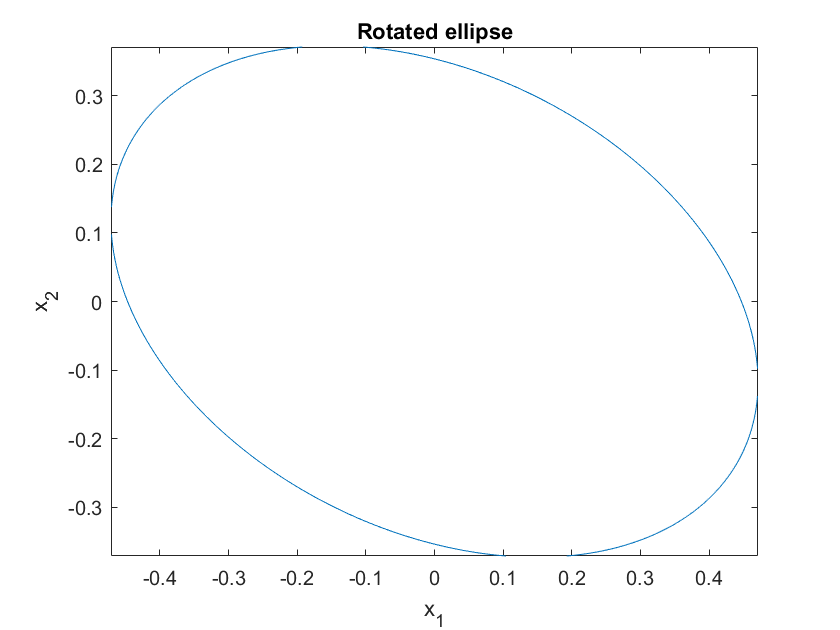

figure
x = sym('x', [2,1], 'real');
fimplicit(5*x(1)^2 + 4*x(1)*x(2) + 8*x(2)^2 - 1)
xlabel x_1, ylabel x_2
axis equal
title('Rotated ellipse')

A = sym([5 2 ; 2 8])

$$A = \left(\begin{array}{cc} 5 & 2\\ 2 & 8 \end{array}\right)$$

expand(x'*A*x)

$$ans = 5\,{x_{1}}^{2}+4\,x_{1}\,x_{2}+8\,{x_{2}}^{2}$$

[V,D] = eig(A), [Q,~] = qr(V)  % just normalise the columns

$$V = \left(\begin{array}{cc} -2 & \frac{1}{2}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 4 & 0\\ 0 & 9 \end{array}\right)$$

$$Q = \left(\begin{array}{cc} -\frac{2\,\sqrt{5}}{5} & \frac{\sqrt{5}}{5}\\ \frac{\sqrt{5}}{5} & \frac{2\,\sqrt{5}}{5} \end{array}\right)$$

isequal(A, Q*D*Q')

ans = logical
   1

y = sym('y', [2,1], 'real');
rotated_ellipse = y'*D*y == 1

$$rotated\_ellipse = 4\,{y_{1}}^{2}+9\,{y_{2}}^{2}=1$$

figure
fimplicit(y'*D*y - 1)
axis equal
title('Ellipse in standard position')

The eigenvalues of $D$ tell us the principal semiaxis lengths.

a = 1/sqrt(D(1,1))  % semimajor axis length

$$a = \frac{1}{2}$$

b = 1/sqrt(D(2,2))  % semiminor axis length

$$b = \frac{1}{3}$$

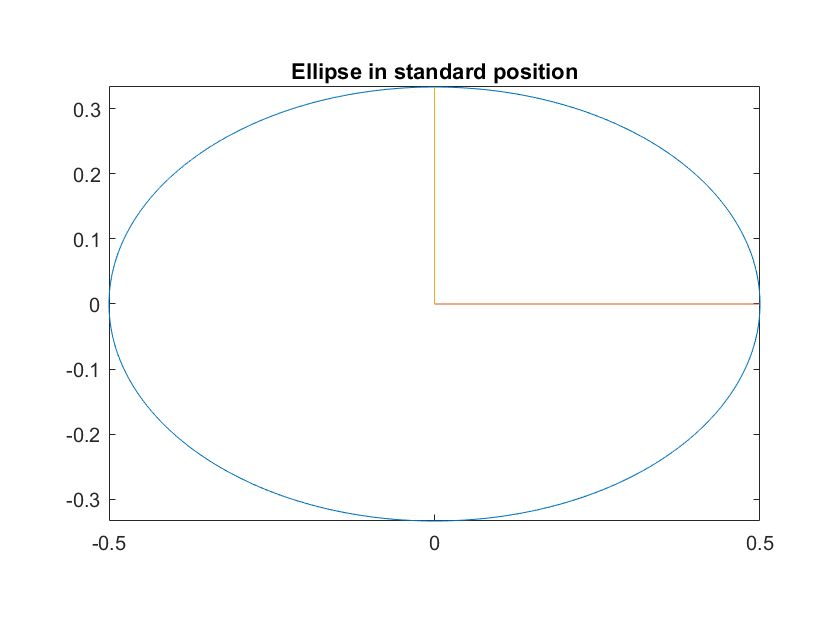

hold on
plot([0 a], [0, 0])
plot([0 0], [0, b])

The eigenvectors give us the rotation angle.  Either column will do:

theta = atan2(Q(2,1), Q(1,1))

$$theta = \pi -\mathrm{atan}\left(\frac{1}{2}\right)$$

double(theta) * 180/pi

ans = 153.4349

So rotate this standard ellipse by 153.5 degrees to get the original one.